# Monte Carlo 蒙特卡罗

## 绘图

## 
$$y=e^x\ \ \ y=-x+e+1 \ \ \ x\in[0,1]$$


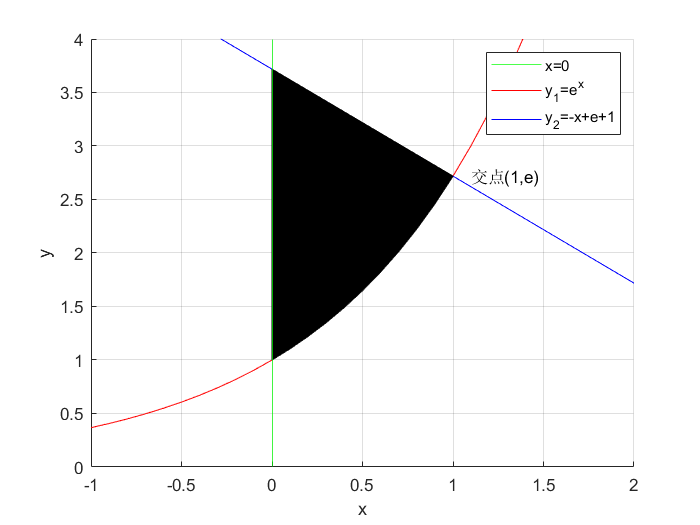

x = -1:0.1:2;
y1 = exp(1).^x;
y2 = -x+exp(1)+1;
figure(1)
hold on
xline(0,'-g');
plot(x,y1,'r',x,y2,'b')
xlabel('x')
ylabel('y')
text(1.1, exp(1), '交点(1,e)');
axis([-1 2 0 4]);
grid on
i = (x>=0 & x<=1);
M1 = [x(i),0];
j = (y1>=1 & y1<=exp(1));
M2 = [y1(i),exp(1)+1];
fill(M1,M2,'k');
legend('x=0','y_1=e^x', 'y_2=-x+e+1');

## 求解

x = unifrnd(0, 1, [1, 10000000]);
y = unifrnd(1, exp(1)+1, [1, 10000000]);
frequency = sum(y<=(-x+exp(1)+1) & y>=exp(1)) + sum(y<=exp(1) & y>=(exp(1).^x));
area = exp(1)*frequency/10^7;
disp("黑色部分面积近似于：")

黑色部分面积近似于：


disp(area);

    1.5009



## 积分

## 
$$\int_{0}^{1}(-x+e+1-e^x)dx=[-\frac{1}{2}x^2+ex+x-e^x]|_{0}^{1}=1.5$$


## 分析

disp("误差百分比：")

误差百分比：


t = abs(area-1.5)/1.5

t = 5.8178e-04

if t <= 0.001
    disp("误差百分比低于  千分之一  认为结果合理.")
else
    disp("误差百分比高于  千分之一  认为结果非法")
end

误差百分比低于  千分之一  认为结果合理.
